1. Compute range of sea level from ALT_Pacific data

clear
load ALT_Pacific.mat % altimeter data
sl_range = NaN(121,161);

for j2 = 1:161
    for j1 = 1:121
        sl = squeeze(ALT.sl(:,j1,j2));
        % time-series length, lat,lon, % remove dimensions of length 1
        % at each time (dim 1), has sea level data at 121 lats (dim 2) and 161 lons
        % (dim 3)
        
        if(~isnan(mean(sl)))
            sl_range(j1,j2) = range(sl); % at each grid point, get different between lowest and max SL
        end
    end
end

% determine trend at every lat lon point

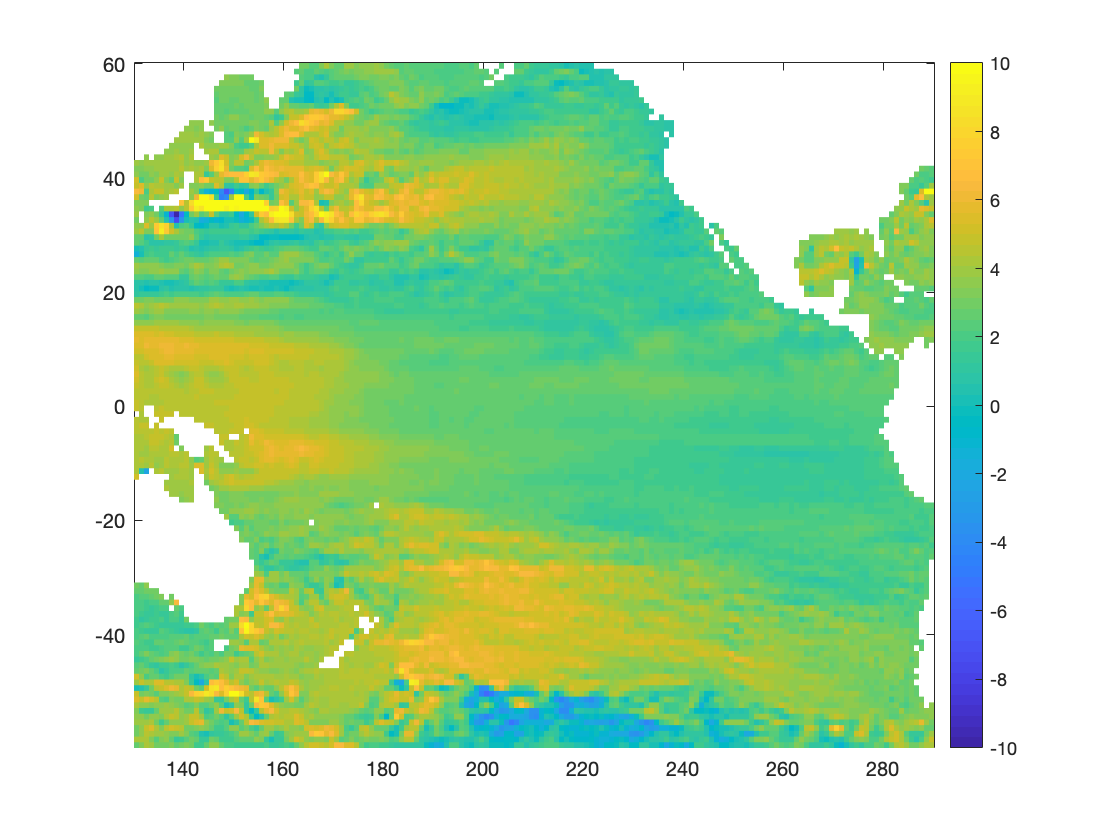

% doing line fit now
sl_trend = NaN(121,161);
x = [ALT.t-mean(ALT.t) ones(311,1)]; % b1 = trend , b2 = mean offset

for j2 = 1:161
    for j1 = 1:121
        sl = squeeze(ALT.sl(:,j1,j2)); % time-series length, lat,lon,  % pull out every point in space the time series
        if(~isnan(mean(sl)))
            b = regress(sl,x); % doing least squares fit for us ( getting coeff by solving the normal eqn )
            sl_trend(j1,j2) = b(1);
        end
    end
end
sl_trend = sl_trend*365.25*1000;  % convert from m/dy to mm/yr
h = pcolor(ALT.lon,ALT.lat,sl_trend);
h.EdgeColor = 'none';
colorbar
caxis([-10 10])

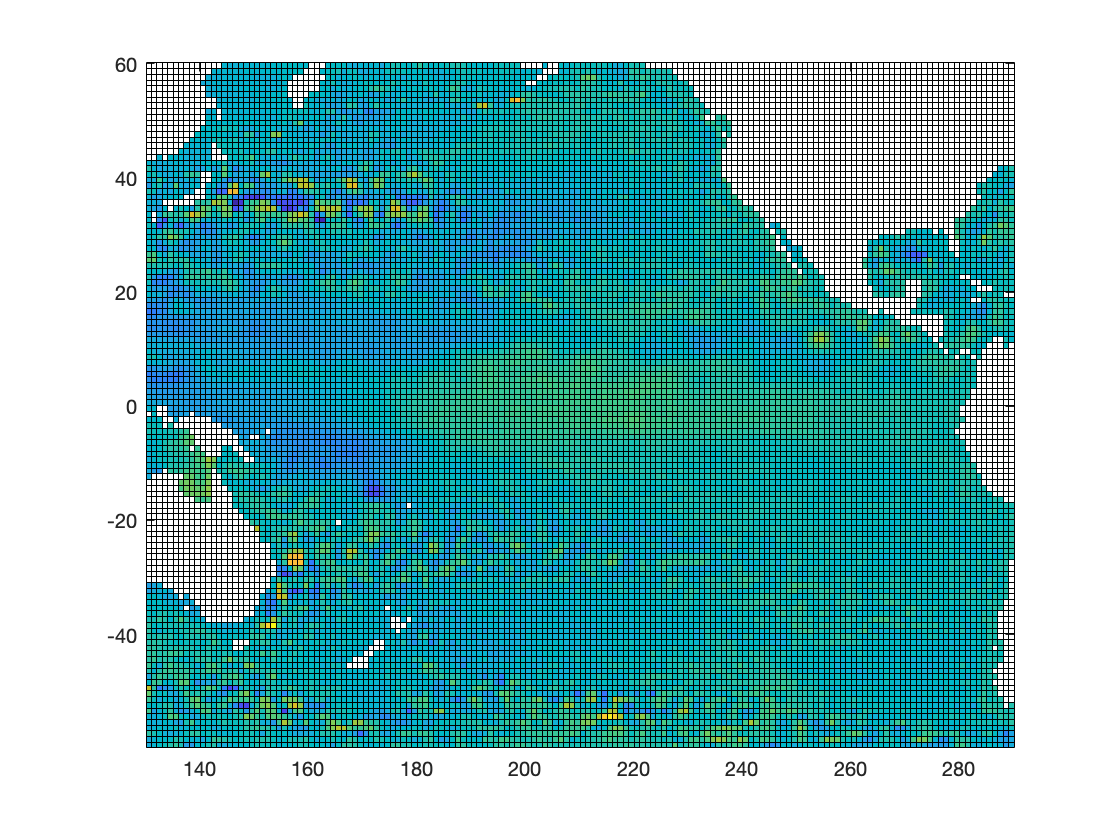

figure(1) % looping in space
for j1=1:311
    sl = squeeze(ALT.sl(j1,:,:));
    pcolor(ALT.lon,ALT.lat,sl);
    pause (2) 
end

Plot using  imagesc 

imagesc(ALT.lon,ALT.lat,sl_range)
set(gca,'YDir','normal')
cb = colorbar;
ylabel(cb,'meters')


Plot using pcolor

pcolor(ALT.lon,ALT.lat,sl_range) % pcolor interpolates between points
cb = colorbar;
ylabel(cb,'meters')
shading 'interp'

2. Remove seasonal cycle, trend, and mean using regress

load TGdata.mat % tide gauge
% TG has 3 stations in it
% example 1 using regression

% removing the ss, trend, and mean using regress all in one
t = TG.t;
hs = TG.sl(:,1);
arg = 2*pi*t/365.25; % one full cycle * time in one calendar year


% x = [t cos(arg) sin(arg) cos(2*arg) sin(2*arg) ones(size(t))];
x = [cos(arg) sin(arg) cos(2*arg) sin(2*arg) ones(size(t))]; % take out linear trend t.
% time , trend, seasonal cycle, mean for code above
b = regress(hs,x); % b=6x1
% multiply each team of b by each term of x below
hsa = hs-x*b;
plot(t,hs,t,hsa);

% example 2 using monthly means
[yr,mo,dy] = datevec(t);
hsa2 = hs;
for j=1:12
    hsa2(mo==j) = hsa2(mo==j)-nanmean(hs(mo==j));
end

figure
plot(t,hsa,t,hsa2) % blue lien is doing regression fit
% red line is the anomaly (seasonal cycle omitted)